data = readtable('../../data/data1/logvRNA.csv');
patients = unique(data.patient,'stable');

x1 = [0.409E-6, 0.233E-6, 0.249, 0.775, 14.5E3, 0.03, 7];
x2 = [0.431E-6, 0.140E-6, 0.077, 0.420, 10E3, 0.021, 24];
x3 = [0.201E-6, 0.001E-6, 0.013, 1.048, 30.172E3, 0.036, 10];
x4 = [9.203E-6, 0.011E-6, 0.013, 0.851, 0.548E3, 0.055, 12];
x5 = [0.485E-6, 0.291E-6, 0.096, 0.803, 11.425E3, 0.033, 5];
x6 = [0.057E-6, 0.004E-6, 0.021, 0.821, 89.892E3, 0.003, 22];

xx = x1;
i = 1
sub_data = data(data.patient == string(patients(i)),:);
dpi = sub_data.dpi;
y = sub_data.log_vRNA;

num_samples = 20;
num_params = size(xx,2);

lb = 0.1 * x1;
up = 10 * x1;

sampled_params = zeros(num_params, num_samples);
for i = 1:num_params
    sampled_params(i,:) = 10.^(linspace(log10(lb(i)),log10(up(i)),num_samples));
end

LSE = zeros(num_params,num_samples);

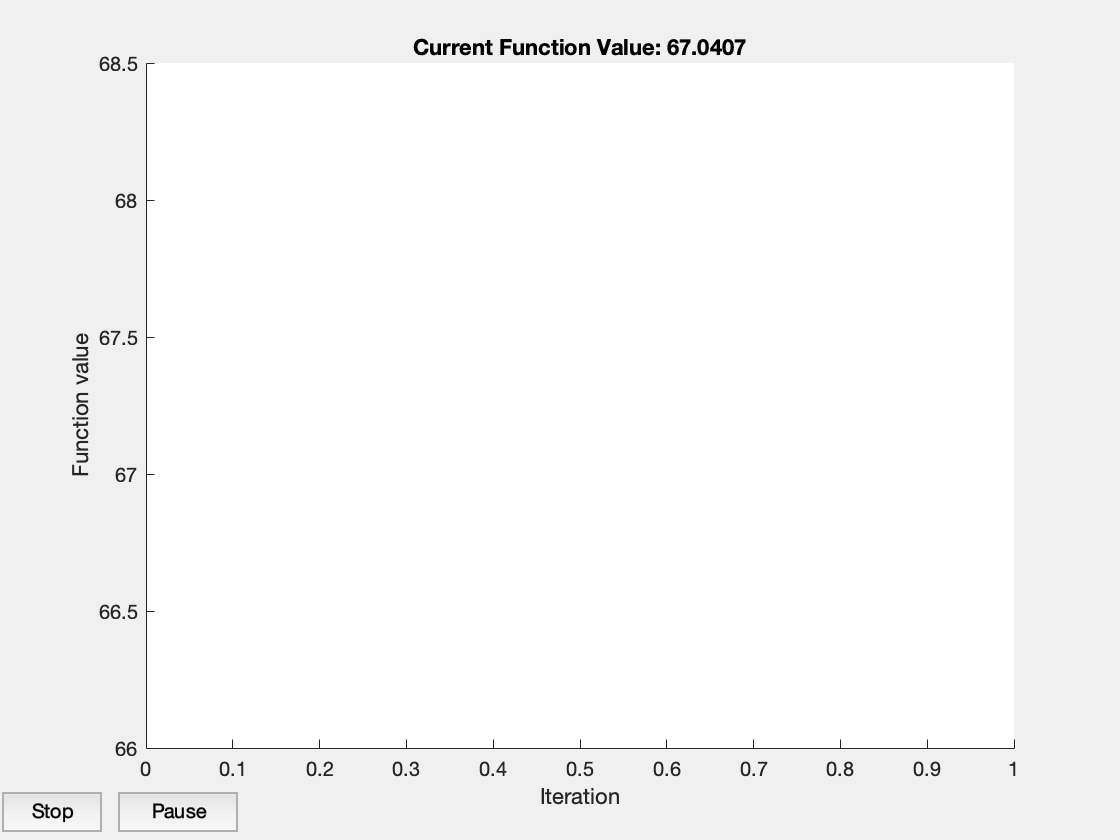

Error using matlab.graphics.chart.primitive.Line/set
Complex values are not supported for 'Y'.

Error in optimplotfval>plotscalar (line 47)
    set(plotfval,'Xdata',newX, 'Ydata',newY);

Error in optimplotfval (line 24)
 

for ip = 1:num_params
    for is = 1:num_samples
        fp = sampled_params(ip,is);
        ic = [xx(1:ip-1) xx(ip+1:end)];
        [opt_param, fval] = best_param(ic,fp,ip,dpi,y);
        LSE(ip,is) = fval;
    end
end 

params = [ic(1:ip-1) fp ic(ip:end)]

params = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0001    1.4500    0.0000    0.0007


J(params,dpi,y)

ans = 67.0407 - 3.3212i

h = 0.01;
ti = 0:h:dpi(end);
V = pred(ti,params)

V =     0.0010
    0.0008
    0.0006
    0.0005
    0.0004
    0.0003
    0.0003
    0.0002
    0.0002
    0.0001


LSE

ans = 1.4142

ans = 2.6651

ans = 2

% The decay function

function out=b(t,b0,bi,k,tau)
    if t <= tau
        out = b0;
    else
        out = bi+(b0-bi)*exp(-k*(t-tau));
    end
end

% using viral dynamic model to predict V
function out = pred(ti,params)
    init = [10^4 0 10^-3];
    b0 = params(1);
    bi = params(2);
    k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);

    f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
            b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    out = xa(:,3);
end

%% least-sqaured error
function out=J(params,dpi,y)
    h = 0.01;
    ti = 0:h:dpi(end);
    V = pred(ti,params);
    y_hat = log10(V(dpi/h+1));
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

%% fix the fp paramter, using fminsearch to optimize others parameters
function [x,fval]=best_param(ic,fp,ip,dpi,y)
    % fp, ip
    options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7); %,'MaxFunEvals', 5000,'MaxIter', 5000);
    JJ = @(params) J([params(1:ip-1) fp params(ip:end)], dpi,y);
    [x,fval] = fminsearch(JJ,ic,options);
end